%https://la.mathworks.com/help/robotics/ref/importrobot.html
robot = importrobot('manipulator_description/urdf/manipulator.urdf');
robot.DataFormat = 'row';
jointData = table2array(datos);
robot.Gravity = [0 0 -9.81];
 

%https://la.mathworks.com/help/robotics/ref/rigidbodytree.velocityproduct.html#refsect-extended-capabilities
% qd = [0 0 0.2 0.3 0 0];
% tau = -velocityProduct(robot,[],qd);

**Jacobiano (configuracion inicial)**

https://la.mathworks.com/help/robotics/ref/rigidbodytree.geometricjacobian.ht**ml**

% conf2 = [0.659 0.831 -1.114 -0.009 0.267 0.638];
% geoJacob = geometricJacobian(robot,conf2,'link_6');


**Valores Propios y Determinante del Jacobiano**

% vp = eig(geoJacob);
% detJacob = det(geoJacob);

**Dinámicas directas debidas a fuerzas externas en el modelo de árbol de cuerpo rígido**

https://la.mathworks.com/help/robotics/ref/rigidbodytree.forwarddynamics.htm**l**

% q = homeConfiguration(robot);
% qdd = forwardDynamics(robot,q,[],[],[]);
% gtau = gravityTorque(robot,q);

**Calcular dinámicas inversas para configurar una articulación estática**

% tau_home = inverseDynamics(robot,q);


 
js = 1;
for i=1:3:length(jointData)
    joint_states(js,:) = jointData(i,:);
    joint_goals(js, : ) = jointData(i+1,:);
    determinante(js)=det(geometricJacobian(robot,deg2rad(jointData(i,:)),'link_6'));
    gtau(js,:) = gravityTorque(robot,deg2rad(jointData(i,:)));
    js = js+1;
end

**Gráfica de los desplazamientos de cada Joint y sus torques**

 
diferencia = joint_states - joint_goals;
for j = 1:4
    figure(1);
    subplot(2,2,j)
    plot(joint_states(:,j),"LineWidth",2)
    grid on
    grid minor
    title("Desplazamiento Joint " + (j - 1))
    xlabel("Iteración")
    ylabel("Desplazamiento (grados)")
    hold on
    plot(joint_goals(:,j),"LineWidth",2)
    legend('Joint State', 'Joint Goal')
    
    figure(2);
    subplot(2,2,j)
    plot(gtau(:,j),"LineWidth",2)
    grid on
    grid minor
    title("Torque por Joint " + (j - 1))
    xlabel("Iteración")
    ylabel("Torque (kg*m)")

    figure(3);
    subplot(2,2,j)
    plot(diferencia(:,j),"LineWidth",2);
    grid on
    grid minor
    title("Diferencia JointStates y JointGoals "+ (j - 1));
    xlabel('Iteración');
    ylabel('Diferencia (grados)');
end

**Gráfica de los determinantes **

figure(4);
plot(determinante,"LineWidth",2)
grid on
grid minor
title("Determinantes usando el Jacobiano de cada configuración")
xlabel("Iteración")
ylabel("Determinante")
hold on;
plot([1, length(joint_states)], [0, 0], 'r--');


**Gráfica de la diferencia entre el JointState y JointGoal**

% diferencia = joint_states - joint_goals;
% 
% figure;
% scatter(1:length(diferencia),diferencia(:,4));
% title('Diferencia entre valores de JointStates y JointGoals');
% xlabel('Índice del joint');
% ylabel('Diferencia');


**Ecuación dinámica para un manipulador**

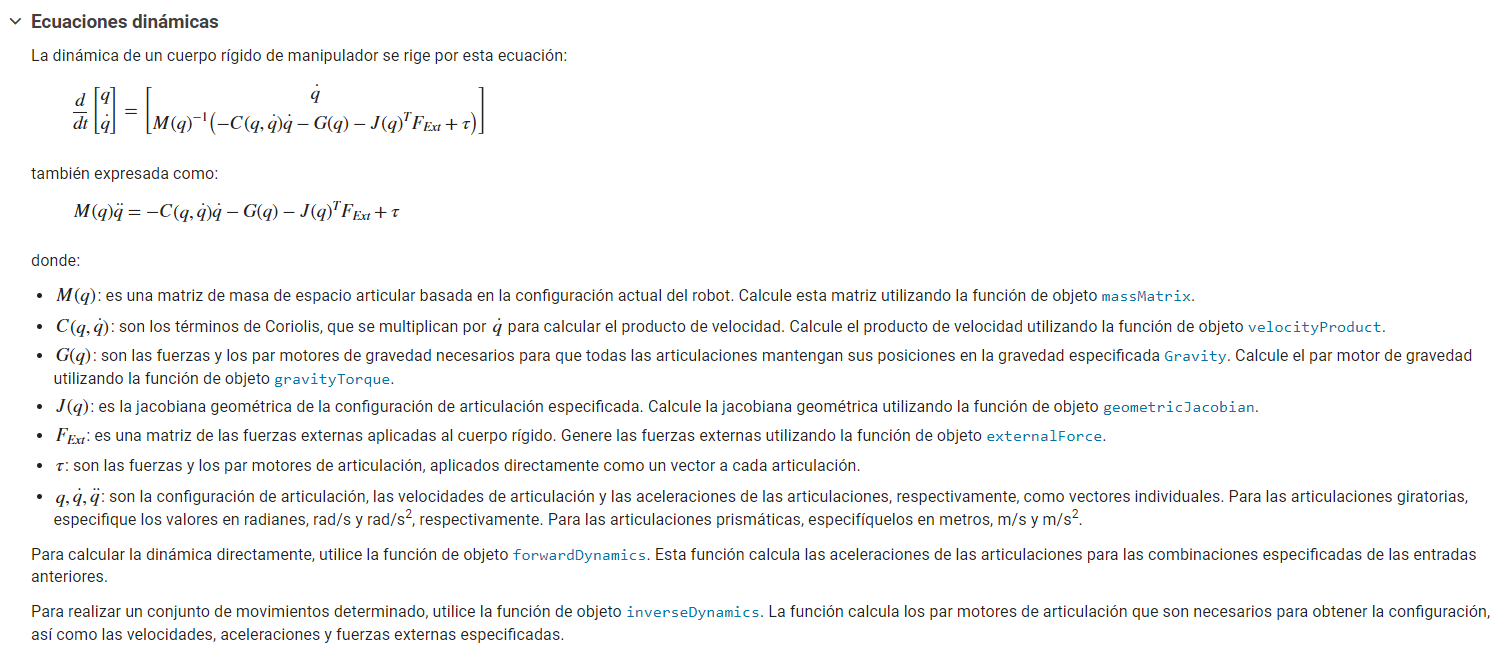

% for i=1:length(joint_states)
%     
%     M(i, :) = massMatrix(robot, joint_states(i,:))*(joint_acc(i, :))';
%     C(i,:) = -velocityProduct(robot, joint_states(i,:),joint_vel(i, :));
%     
% end
% 
% tau = M + C + gtau